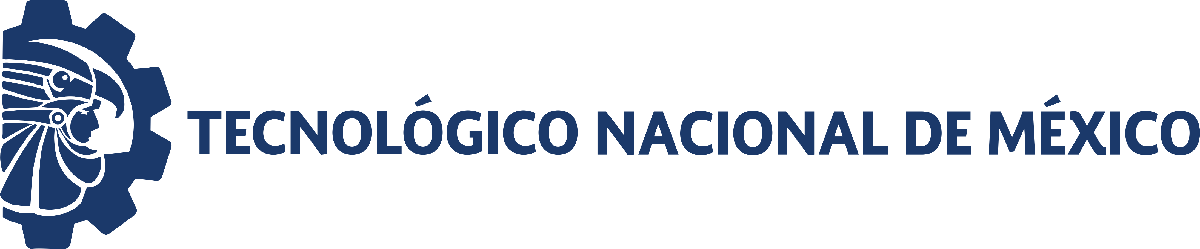                                 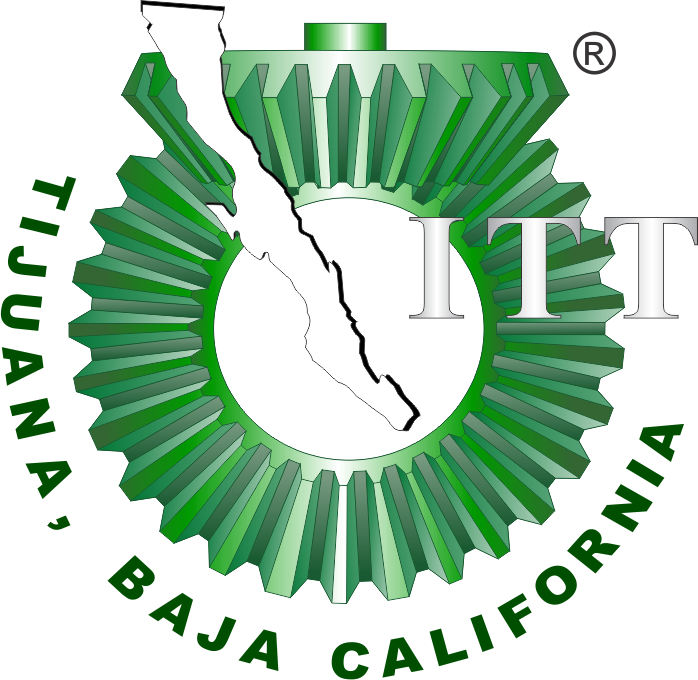

# Práctica 0: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[Foto]

Nombre del alumno: **Nombres y Apellidos**

Número de control: **12345678**

Correo institucional: **xxx.xxx@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';
parameters.MaxStep = '1E-3';
Controlador = 'PID';

## Respuesta al escalón

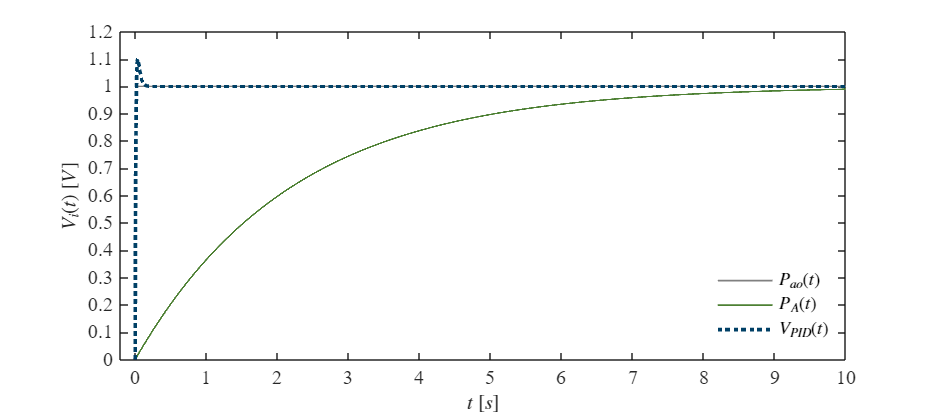

Signal = 'Escalon';
set_param('Sistema/S1','sw','1');
set_param('Sistema/Pao(t)','sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Pao,x1.PA,x1.VPID,Controlador,Signal)

## Respuesta al impulso

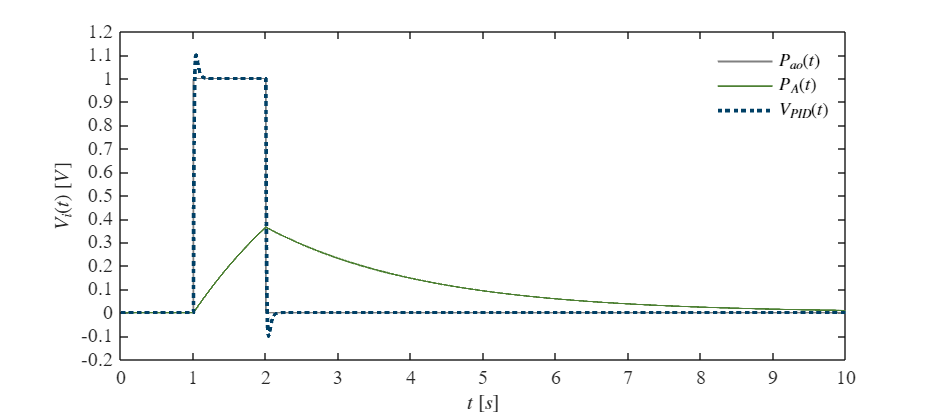

Signal = 'Impulso';
set_param('Sistema/S1','sw','0');
set_param('Sistema/Pao(t)','sw','1');
x2 = sim(file,parameters);
plotsignals(x2.t,x2.Pao,x2.PA,x2.VPID,Controlador,Signal)

## Respuesta a la rampa

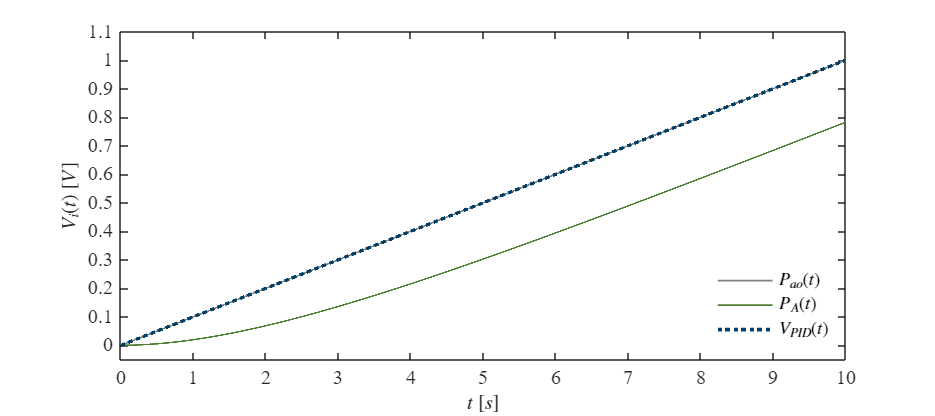

Signal = 'Rampa';
set_param('Sistema/S2','sw','1');
set_param('Sistema/Pao(t)','sw','0');
x3 = sim(file,parameters);
plotsignals(x3.t,x3.Pao,x3.PA,x3.VPID,Controlador,Signal)

## Respuesta a la función sinusoidal

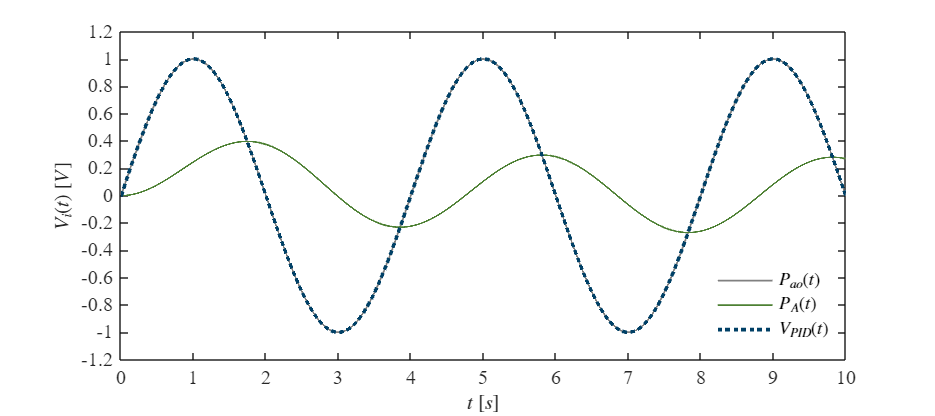

Signal = 'Sin';
set_param('Sistema/S2','sw','0');
set_param('Sistema/Pao(t)','sw','0');
x4 = sim(file,parameters);
plotsignals(x4.t,x4.Pao,x4.PA,x4.VPID,Controlador,Signal)

## Función: Respuesta a las señales

function plotsignals(t,Ve,Vs,VPID,Controlador,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on
    
    plot(t,Ve,'LineWidth',1,'Color',[0.5,0.5,0.5])
    plot(t,Vs,'LineWidth',1,'Color',[0.3,0.5,0.2])
    plot(t,VPID,':','LineWidth',2,'Color',[0,0.25,0.4])
    
    L = legend('$P_{ao}(t)$','$P_A(t)$',['$V_{',Controlador,'}(t)$']);
    set(L,'Interpreter','Latex','FontSize',10,'location','best','box','off')
    
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$V_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    
    if Signal == "Escalon"
        xlim([-0.2,10]); xticks(0:1:10)
        ylim([0,1.2]); yticks(0:0.1:1.2)
    elseif Signal == "Impulso"
        xlim([0,10]); xticks(0:1:10)
        ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2)
    elseif Signal == "Rampa"
        xlim([0,10]); xticks(0:1:10)
        ylim([-0.05,1.1]); yticks(0:0.1:1.2)
    elseif Signal == "Sin"
        xlim([0,10]); xticks(0:1:10)
        ylim([-1.2,1.2]); yticks(-1.2:0.2:1.2)
    end
    
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal,'.png'],'Resolution',600);
    print(Signal,'-dsvg','-r600');
    print(Signal,'-depsc','-r600')
end